clear 
G=2.1686;   
R=48.9120; 
c=114.2959;

A=-1/(R*c);
B=[1/(R),G];
C=1/c;
D=[0,0];

Ta=22;
x0=Ta;
th=-22;
th2=-20;



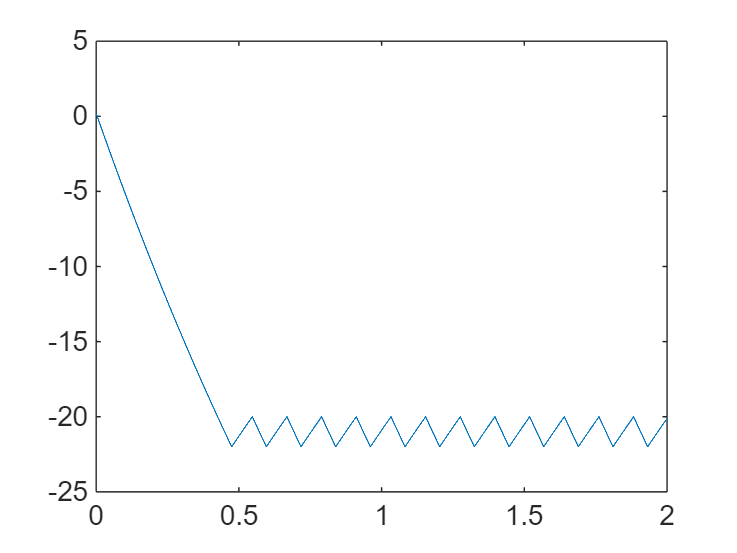

stopTime=2*60*60;
fs=1;
dt=1/fs;
t=0:dt:stopTime;
Ta=22*ones(1,fs*stopTime+1);
Tas=timeseries(Ta,t);
out=sim('modelControl');
plot(t/(60*60),out.Y.Data)

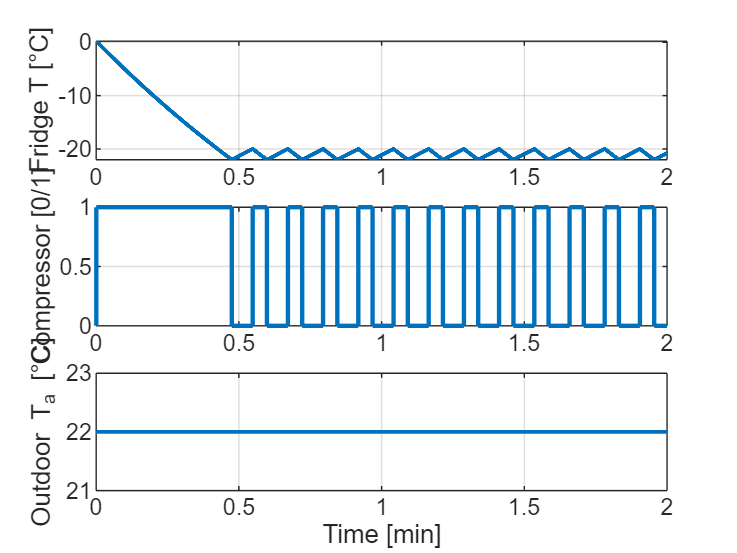


%fridge_closed_loop();
simData=fridge_fixed_step(Ta,G,R,c,t,x0);
figure
subplot(3,1,1)
plot(t/(60*60),simData.y,'LineWidth',1.5), grid on
ylabel('Fridge T [°C]')

subplot(3,1,2)
stairs(t/(60*60),-simData.u1,'LineWidth',1.5), grid on
ylabel('Compressor [0/1]')

subplot(3,1,3)
plot(t/(60*60),simData.u2,'LineWidth',1.3), grid on
xlabel('Time [min]')
ylabel('Outdoor T_a [°C]')

% Ta,G,R,C,t,x0,fs

% function simData = fridge_fixed_step()
% % Discrete-time simulation of a refrigerator with hysteresis control
% % ––– USER DEFINED SYSTEM ––– ------------------------------------------
% 
% G=2.1686;   
% R=48.9120; 
% c=114.2959;
% 
% A = -1/(R*c);                  % n×n   ← copy from your State‑Space block
% B = [G,1/R];                  % n×2
% C = 1/c;                  % 1×n
% D = [0,0];                  % 1×2
% 
% dt     = 1;                % time step [s]
% Tend   = 2*3600;           % simulate 2 hours
% t      = 0:dt:Tend;        % time vector
% Ta_fun = @(t) 25;  % outdoor temperature
% 
% n   = size(A,1);
% x   = zeros(n,length(t));
% x0  = zeros(n,1);         % initial state
% x(:,1) = x0;
% 
% y  = zeros(1,length(t));
% u1 = zeros(1,length(t));
% u2 = arrayfun(Ta_fun, t);
% 
% % ––– Hysteresis controller state
% heater = 0;               % compressor OFF initially
% T_low  = -22;               % °C, turn ON below this
% T_high = -20;               % °C, turn OFF above this
% 
% % ––– MAIN LOOP ––– -----------------------------------------------------
% for k = 1:length(t)-1
%     y(k) = C*x(:,k) + D*[u1(k); u2(k)];
% 
%     % Controller logic (hysteresis)
%     if y(k) < T_low
%         heater = 0;
%     elseif y(k) > T_high
%         heater = -1;
%     end
%     u1(k+1) = heater;
% 
%     % Plant update (Euler integration)
%     u = [u1(k); u2(k)];
%     dx = A*x(:,k) + B*u;
%     x(:,k+1) = x(:,k) + dt * dx;
% end
% y(end) = C*x(:,end) + D*[u1(end); u2(end)];
% 
% % ––– OUTPUT ––– --------------------------------------------------------
% 
% simData = struct('t',t,'x',x,'y',y,'u1',u1,'u2',u2);
% 
% figure
% subplot(3,1,1)
% plot(t/60,y,'LineWidth',1.5), grid on
% ylabel('Fridge T [°C]')
% 
% subplot(3,1,2)
% stairs(t/60,u1,'LineWidth',1.5), grid on
% ylabel('Compressor [0/1]')
% 
% subplot(3,1,3)
% plot(t/60,u2,'LineWidth',1.3), grid on
% xlabel('Time [min]')
% ylabel('Outdoor T_a [°C]')
% end



% function simData = fridge_closed_loop()
% % Closed‑loop simulation of a refrigerator with a hysteresis controller
% % ––– USER SECTION ––– -------------------------------------------------
% 
% G=2.1686;   
% R=48.9120; 
% c=114.2959;
% 
% A = -1/(R*c);                  % n×n   ← copy from your State‑Space block
% B = [1/(R),G];                  % n×2
% C = 1/c;                  % 1×n
% D = [0,0];                  % 1×2
% 
% x0      = 0;   % initial states, edit if needed
% tspan   = [0 2*3600];           % simulate two hours [s]
% Ta_fun  = @(t) 25 + 3*sin(2*pi*t/86400);  % outdoor temp profile
% 
% % on/off compressor controller with hysteresis:
% ctrl_fun = @(T, t) compressor_hyst_ctrl(T);
% 
% % ––– SIMULATION ––– ---------------------------------------------------
% odefun = @(t,x) plant_ode(t,x,A,B,C,D,Ta_fun,ctrl_fun);
% [t,x]  = ode45(odefun,tspan,x0);           % integrate
% 
% % post‑process outputs
% y  = (C*x.')' + D(:,2) .* arrayfun(Ta_fun,t).';   % fridge temperature
% u1 = arrayfun(@(ti,yi) ctrl_fun(yi,ti), t, y);    % compressor command
% u2 = arrayfun(Ta_fun,t).';                        % outside temp
% 
% simData = struct('t',t,'x',x,'y',y,'u1',u1,'u2',u2);
% 
% % quick plot
% figure, subplot(2,1,1)
% plot(t/60,y,'LineWidth',1.4), grid on
% xlabel('Time [min]'), ylabel('T_{fridge} [°C]')
% 
% subplot(2,1,2)
% stairs(t/60,u1,'LineWidth',1.6), grid on
% xlabel('Time [min]'), ylabel('Compressor ON=1/OFF=0')
% ylim([-0.1 1.1])
% 
% end
% % ----------------------------------------------------------------------
% 
% function dx = plant_ode(t,x,A,B,C,D,Ta_fun,ctrl_fun)
% %   Computes  ẋ = A x + B u  with u = [u1; u2]
%     y   = C*x + D(:,2)*Ta_fun(t);  % output before adding u1 term
%     u1  = ctrl_fun(y,t);
%     u   = [u1; Ta_fun(t)];
%     dx  = A*x + B*u;
% end
% % ----------------------------------------------------------------------
% 
% function u = compressor_hyst_ctrl(T)
% %   Simple hysteresis controller:
% %   turn ON below T_low, OFF above T_high, hold otherwise
%     persistent state
%     if isempty(state), state = 0; end          % start OFF
% 
%     T_low  = 2;     % [°C] adjust to taste
%     T_high = 4;
% 
%     if  T < T_low
%         state = 1;  % switch ON
%     elseif T > T_high
%         state = 0;  % switch OFF
%     end
%     u = state;
% end
% 




